
%#ok<*CLALL>

clear all;clc 

% Sim settings. 
maxSpeed = 1E-1; 
timeStep = 4; 

% Initial states. 
initialStates = [-1; 0; 1; 0; maxSpeed; 0; 0; maxSpeed]; 
x_c_0 = [-1; 0]; 
x_e_0 = [1; 0; 0; maxSpeed]; 

% Position constraints. 
areaBounds = [-1; 1; -1; 1]*50; 

% Position constraint test. 
% areaBounds(2) = -0.5; 

% TPBVP test time span input. 
tspan = 0 : 1E-2 : timeStep; 

% Initial guess. 
% guess = [ ...
%     initialStates; ...
%     (initialStates(1)-initialStates(3)); ...
%     (initialStates(2)-initialStates(4)); ...
%     -(initialStates(1)-initialStates(3)); ...
%     -(initialStates(2)-initialStates(4)); ...
%     zeros(4, 1)]; 
guess = [ ...
    x_e_0(1:2); 
    x_e_0(1:2)+timeStep.*x_e_0(3:4)]; 
disp(guess); 

    1.0000
         0
    1.0000
    0.4000



solGuess = bvpinit(tspan, guess); 
options = bvpset("Stats", "on"); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, maxSpeed, areaBounds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b, x_c_0, x_e_0, timeStep), ...
    solGuess, options); 

The solution was obtained on a mesh of 401 points.
The maximum residual is  6.715e-05. 
There were 8022 calls to the ODE function. 
There were 29 calls to the BC function. 


solGuess = bvpinit(tspan, sol.y(:, end)); 
sol = bvp4c( ...
    @(t, y) eqns(t, y, maxSpeed, areaBounds), ...
    @(y_a, y_b) boundaryConditions(y_a, y_b, x_c_0, x_e_0, timeStep), ...
    solGuess, options); 

The solution was obtained on a mesh of 401 points.
The maximum residual is  8.679e-11. 
There were 4011 calls to the ODE function. 
There were 14 calls to the BC function. 


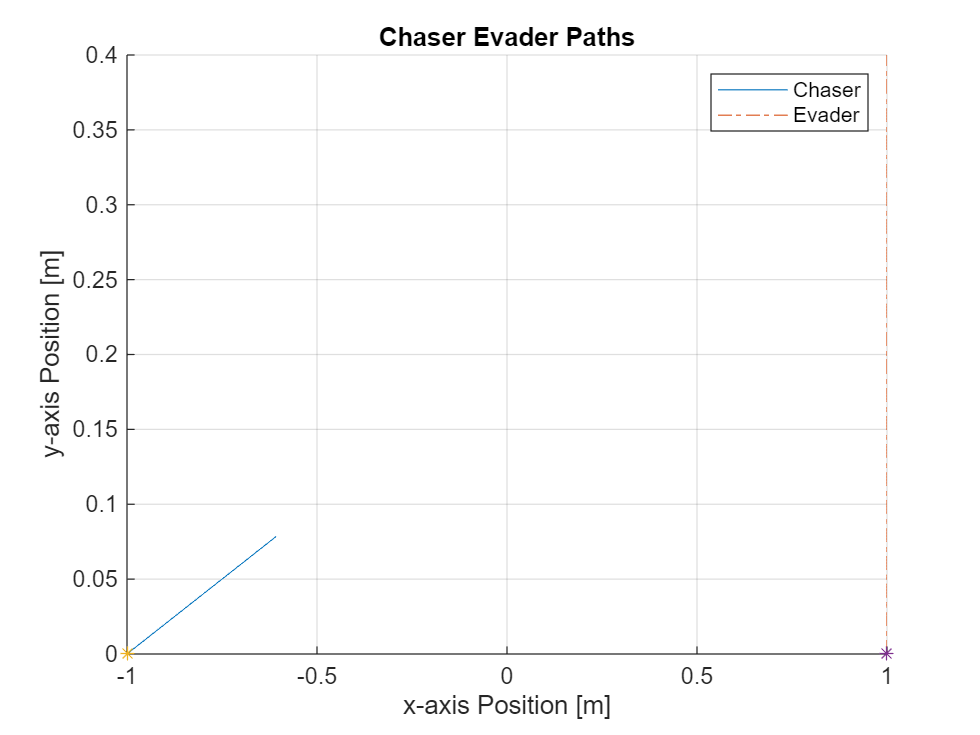

tspan = sol.x; 
y = sol.y; 
chaserPath = y(1:2, :); 
evaderPath = x_e_0(1:2)+tspan.*x_e_0(3:4); 

clf; 
hold on; 
grid on; 
plot(chaserPath(1, :), chaserPath(2, :)); 
plot(evaderPath(1, :), evaderPath(2, :), "-."); 
plot(chaserPath(1, 1), chaserPath(2, 1), "*"); 
plot(evaderPath(1, 1), evaderPath(2, 1), "*"); 
title("Chaser Evader Paths"); 
xlabel("x-axis Position [m]"); 
ylabel("y-axis Position [m]"); 
legend("Chaser", "Evader"); 
% axis([-2 1 -1 1.6]); 
hold off;  

% clf; 
% hold on; 
% grid on; 
% plot(tspan, sqrt(y(5, :).^2+y(6, :).^2)); 
% plot(tspan, sqrt(y(7, :).^2+y(8, :).^2)); 
% title("Chaser Evader Speeds"); 
% xlabel("time [sec]"); 
% ylabel("Drone Speed"); 
% legend("Chaser", "Evader"); 
% hold off; 
% Differential equations. 
function dydt = eqns(~, y, maxSpeed, areaBnds)
    u = atan2(y(4), y(3)) + pi; 

    mu = max([ ...
        areaBnds(1)-y(1); ...
        y(1)-areaBnds(2); ...
        areaBnds(3)-y(2); ...
        y(2)-areaBnds(4)], 0); 

    dydt = [ ...
        maxSpeed*cos(u); ...
        maxSpeed*sin(u); ...
        mu(2)-mu(1); ...
        mu(4)-mu(3)]; 
end

% Boundary conditions. 
function retval = boundaryConditions(y_a, y_b, x_c_0, x_e_0, timeStep)
    retval = [ ...
        y_a(1:2)-x_c_0; ...
        y_b(3:4) - [ ...
        y_b(1)-(x_e_0(1)+timeStep*x_e_0(3)); ...
        y_b(2)-(x_e_0(2)+timeStep*x_e_0(4))]]; 
end